
Single objective optimization:
2 Variable(s)
2 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2508           -99           10      0
Optimization terminated: no feasible point found.


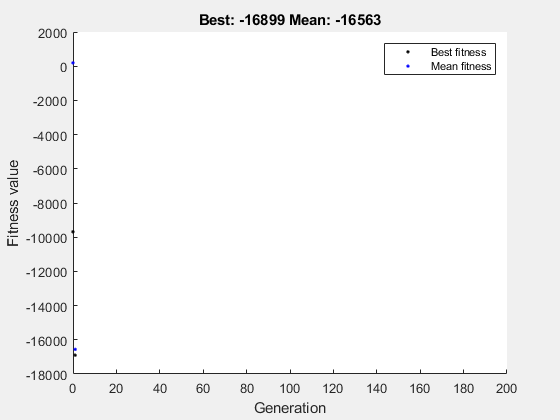

objectiveFcn = @(x) 100 * (x(1)^2 - x(2)^2) + (1 - x(1))^2;

nonlincon = @(x) deal(...
    [x(1) * x(2) + x(1) - x(2) + 1.5; 10 - x(1) * x(2)], ...
    []);
% Границы переменных
lb = [0, 1];
ub = [0, 13];

options = optimoptions('ga', ...
    'Display', 'iter', ...
    'PlotFcn', @gaplotbestf);

[x_opt, fval] = ga(objectiveFcn, 2, [], [], [], [], lb, ub, nonlincon, options);

disp('Оптимальное решение:');

Оптимальное решение:


disp(x_opt);

     0     1



disp('Минимальное значение целевой функции:');

Минимальное значение целевой функции:


disp(fval);

   -99

